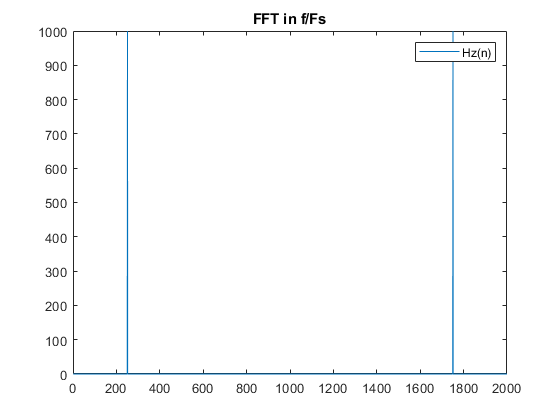

Fs=16000;
n=1:2000;
x=sin(2*pi*n*2000/Fs);%normalisoitu taajuus =f/Fs
plot(n,abs(fft(x)))
title('FFT in f/Fs')
legend('Hz(n)')

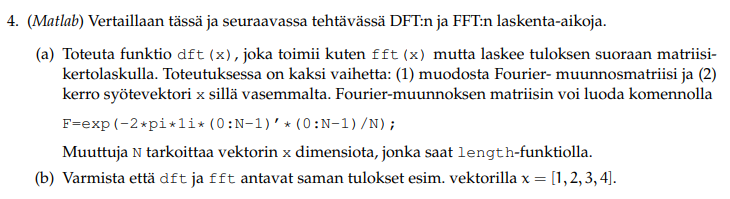


syms x
N=length(x);
F=exp(-2*pi*1i*(0:N-1)'*(0:N-1)/N);
%(b)
x=[1,2,3,4]

x =      1     2     3     4


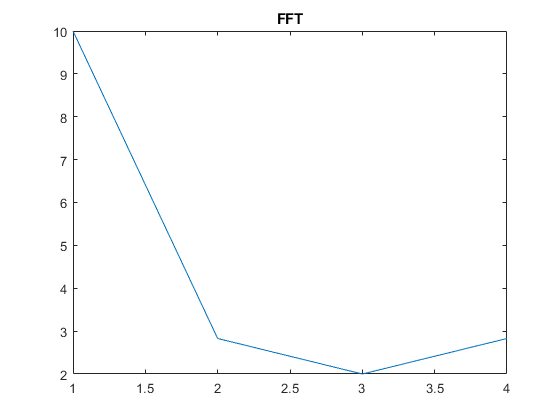

plot(x,abs(fft(x)))
title('FFT')

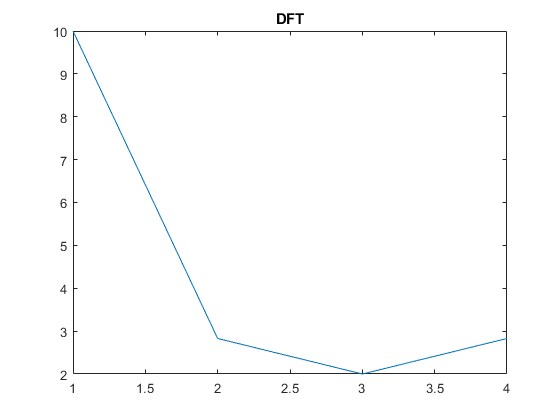

plot(x,abs(dft(x)))
title('DFT')

%function result=dft(x)
%    N=length(x);
%    F=exp(-2*pi*1i*(0:N-1)'*(0:N-1)/N);
%    result=x*F;
%end



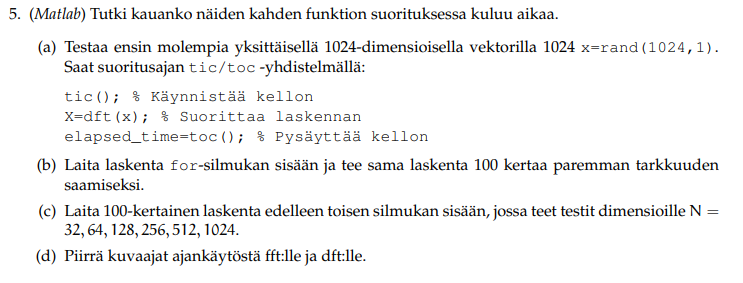

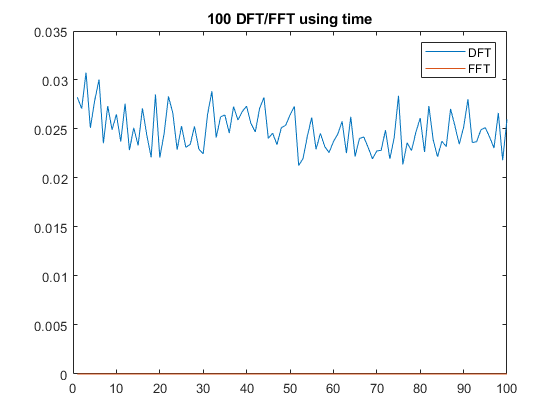



x=rand(1024,1);
tic(); % Käynnistää kellon
X=dft(x'); % Suorittaa laskennan(pilkku on tärkeä)
elapsed_time=toc(); % Pysäyttää kellon
%(b)
times=zeros(100);
for  i=1:100
    tic(); 
    X=dft(x'); 
    times(i)=toc(); 
end
plot(times)
title('100 DFT/FFT using time')
hold off% hold off first then 'legend' works
legend('DFT','FFT')

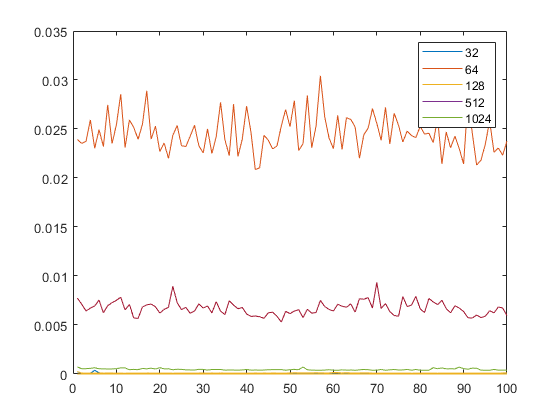

%(c)
% DFT

for N = [32, 64, 128, 512, 1024]
    x = rand(N,1)';
    for  i=1:100
        tic(); 
        X=dft(x); 
        times(i)=toc(); 
    end
    plot(times)
    hold on
    legend({'32', '64', '128', '512', '1024'})
end

hold off 

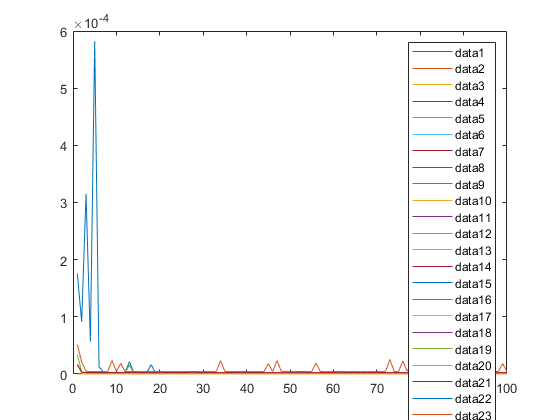

% FFT

for N = [32, 64, 128, 512, 1024]
    x = rand(N,1)';
    for  i=1:100
        tic(); 
        X=fft(x'); 
        times(i)=toc(); 
    end
    plot(times)
    hold on
end
hold off
legend


function result=dft(x)
    N=length(x);
    F=exp(-2*pi*1i*(0:N-1)'*(0:N-1)/N);
    result=x*F;
end
